clear;
clc;
SG = load("Data and plots\HalfLekaSlippingonMatsRaibert1.mat");
SS = load("Data and plots\20SStableRunSimscape.mat");

tStart = 19270; %ms
tEnd = 32490; %ms - somewhat through last flight
dySG = timeseries2timetable(SG.data{9}.Values.dy);

ySG = timeseries2timetable(SG.data{9}.Values.y);

dxSG = timeseries2timetable(SG.data{9}.Values.dx);


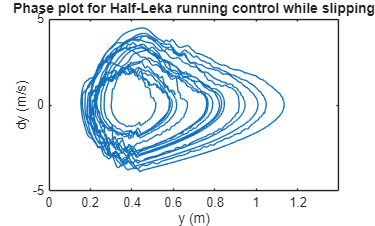


% Final plots
plot(ySG.y(tStart:tEnd),dySG.dy(tStart:tEnd));
hold on
xlabel("y (m)")
ylabel("dy (m/s)")
title("Phase plot for Half-Leka running control while slipping")
axis([0 1.4 -5 5])
hold off

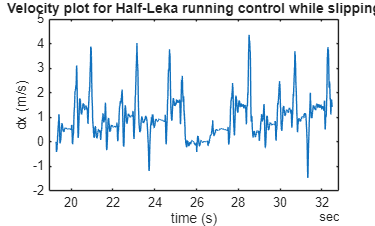


plot(dxSG.Time(tStart:tEnd), dxSG.dx(tStart:tEnd))
hold on
xlabel("time (s)")
ylabel("dx (m/s)")
title("Velocity plot for Half-Leka running control while slipping")
hold off

dySS = timeseries2timetable(SS.data{9}.Values.dy);
ySS = timeseries2timetable(SS.data{9}.Values.y);

dxSS = timeseries2timetable(SS.data{9}.Values.dx);

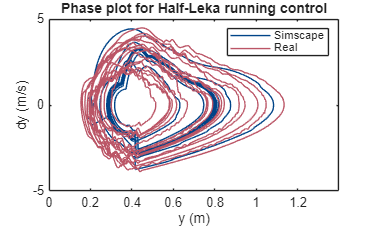

% Final plots
plot(ySS.y,dySS.dy, Color='#004488');
hold on
plot(ySG.y(tStart:tEnd),dySG.dy(tStart:tEnd), Color='#BB5566');
xlabel("y (m)")
ylabel("dy (m/s)")
title("Phase plot for Half-Leka running control")
axis([0 1.4 -5 5])
legend("Simscape", "Real")
hold off

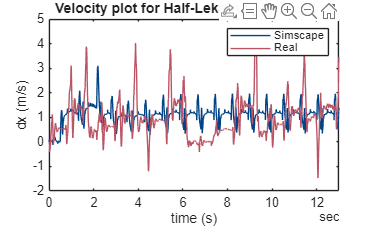


tStarts = 19.270; %s
tEnds = 32.490; %s - somewhat through last flight
Ts = 1000;
trimdx = dxSG.dx(tStart:tEnd);
trimT = dxSG.Time(1:tEnd -tStart+1);

linwidth = 1.5;
t = linspace(0, (tEnds - tStarts), (tEnds - tStarts)*Ts+1);
% resampleDx = resample(dxSS.dx, dxSG)
% Need to resample
% temp = TestsTorque.data{4}{14}.Values.t;
% StaticFricTcmd = resample(TestsTorque.data{3}{3}.Values.tff, temp.Time);
plot(dxSS.Time, dxSS.dx, Color='#004488')
hold on
plot(dxSG.Time(1:tEnd -tStart+1), dxSG.dx(tStart:tEnd), Color='#BB5566')
xlabel("time (s)")
ylabel("dx (m/s)")
title("Velocity plot for Half-Leka running control")
legend("Simscape", "Real")
xlim([seconds(0) seconds(13)])
hold off